# Get Started with Solver-Based Optimize Live Editor Task

This example script helps you to use the solver-based **Optimize** Live Editor task for optimization or equation solving. Modify the script for your own problem.

The script solves a nonlinear optimization problem with nonlinear constraints.

## Include Parameters or Data

clear; clc;
nvars = 10;
      %h0 h1 z2 w1  w2  w3 w4 w5 q1  Ic 
A =   [];
b =   [];
Aeq = [];
beq = [];
%     h0 h1 z2 w1 w2 w3 w4 w5 q1 Ic
lb = [ 0; 0; 0; 0; 0; 0; 0; 0; 0; 0];
ub = [ 1; 1; 1; 1; 1; 1; 1; 1; 1; 1];

**Place the **`x0`** value and any other problem data into the workspace** by running this section before proceeding.

## Optimize Live Editor Task

Optimization terminated: average change in the spread of Pareto solutions less than options.FunctionTolerance.


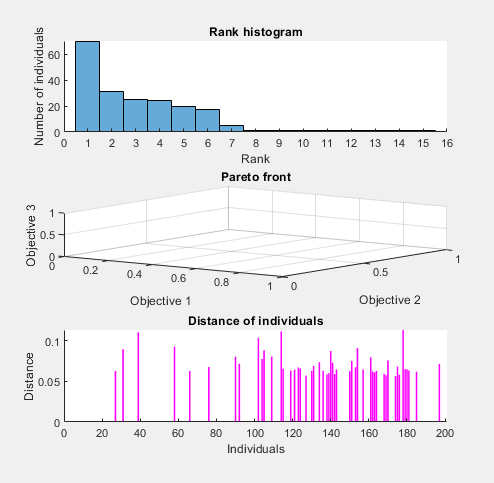

% Set nondefault solver options
options2 = optimoptions("gamultiobj","UseParallel",true,"PopulationSize",200,...
    "MaxGenerations",2000,"PlotFcn",["gaplotrankhist","gaplotpareto",...
    "gaplotparetodistance"]);

% Solve
[solution,objectiveValue] = gamultiobj(@objfunMCA,nvars,[],[],[],[],lb,ub,[],...
    [],options2);


% Clear variables
clearvars options2

## Results

`Optimize` saves the solution to the workspace variable `solution`, and saves the objective function value at the solution to the workspace variable `objectiveValue`. You can see and modify these variable names at the top of the `Optimize` task.

View these variables.

solution

solution =     0.3522    0.8417    0.3956    0.0000    0.3659    0.9910    0.3954    0.2161    0.9798    0.9700
    0.9534    0.1020    0.6610    0.9542    0.4004    0.3913    0.0003    0.9272    0.2463    0.5940
    0.8907    0.8415    0.2360    0.3262    0.0002    0.6034    0.6454    0.8925    0.4494    0.9076
    0.6875    0.0000    0.5590    0.6782    0.7775    0.0824    0.5480    0.2292    0.3809    0.8780
    0.7773    0.3077    0.7516    0.8224    0.9002    0.0001    0.6801    0.3012    0.4974    0.7665
    0.0006    0.8413    0.2763    0.2067    0.3979    0.9252    0.5599    0.2743    0.8894    0.8258
    0.9867    0.9812    0.1859    0.2738    0.7381    0.8535    0.4534    0.6261    0.9442    0.0428
    0.2731    0.5728    0.0001    0.2396    0.8514    0.7626    0.3848    0.8250    0.5200    0.8406
    0.1535    0.2778    0.1477    0.7671    0.1517    0.9430    0.8340    0.0002    0.8134    0.7507
    0.8106    0.3778    0.9139    0.4595    0.7030    0.6927    0.2877    0.9256

objectiveValue

objectiveValue = 1.0e+08 *

    6.9086    6.9086       NaN
    0.0149    0.0149       NaN
    0.0156    0.0156       NaN
    0.0257    0.0257       NaN
    0.0130    0.0130       NaN
    0.0375    0.0375       NaN
    0.0275    0.0275       NaN
    0.0540    0.0540       NaN
    0.0017    0.0017       NaN
    0.0165    0.0165       NaN


View the nonlinear constraint function values at the solution.

%[F1,c1,xD1,R1] = objfunMCA(solution(1,:))

Compare with FEMM results

%[F2,c2,xD2,R2] = objfunFEMM(solution(1,:),true)
[m,n] = size(solution);
ValidResults = struct;
counter = 0;
for i = 1:m
    fprintf('Testing Design %d: ',i)
    [F2,c2,xD2,R2] = objfunFEMM(solution(i,:),false);
    if sum(c2(2:3,:),"all") == 0
        counter = counter + 1;
        saveString = sprintf("result%d",counter); 
        ValidResults.(saveString).objectives = F2;
        ValidResults.(saveString).constraints = c2(1,:);
        ValidResults.(saveString).designString = xD2;
        ValidResults.(saveString).optimizeString = solution(i,:);
        ValidResults.(saveString).extraResistance = R2(1);
        ValidResults.(saveString).Mass = R2(2:3);
        ValidResults.(saveString).Power = R2(4);
        ValidResults.(saveString).Vwaste = R2(5);
        fprintf('Valid\n')
    else
        LC1 = find(c2(2,:))
        LC2 = find(c2(3,:))
        fprintf('Invalid\n')
        fprintf('%d Too Low\n')
        fprintf('%dToo High\n')
    end
end

Testing Design 1: 

Invalid


Testing Design 2: 

Invalid


Testing Design 3: 

Invalid


Testing Design 4: 

Invalid


Testing Design 5: 

Invalid


Testing Design 6: 

Invalid


Testing Design 7: 

save("results.mat","solution","objectiveValue","ValidResults")